## 1. LOAD DATA

clear

## Import gridded data

% The LiDAR data are stored as an ArcGIS-formatted ASCII grid (*.asc)
% [Z, dim] = ReadArcGrid('Data/chiri_20110611ground_sor_rotated_kriglinisotropy1_10cm_trimmed.asc');
[Z, dim] = ReadArcGrid('Data/chiri_20120314ground_sor_rotated_kriglinisotropy1_10cm_trimmed.asc');

% The struct variable dim contains fields describing the coordinates and
% dimensions of Z. These are based on the information extracted from the
% grid file header.
dx = 0.1; %abs(dim.x(2) - dim.x(1)); % grid spacing in the x-direction
dy = 0.1; %abs(dim.y(2) - dim.y(1)); % grid spacing in the y-direction
[Ny Nx] = size(Z); % grid dimensions

## View data

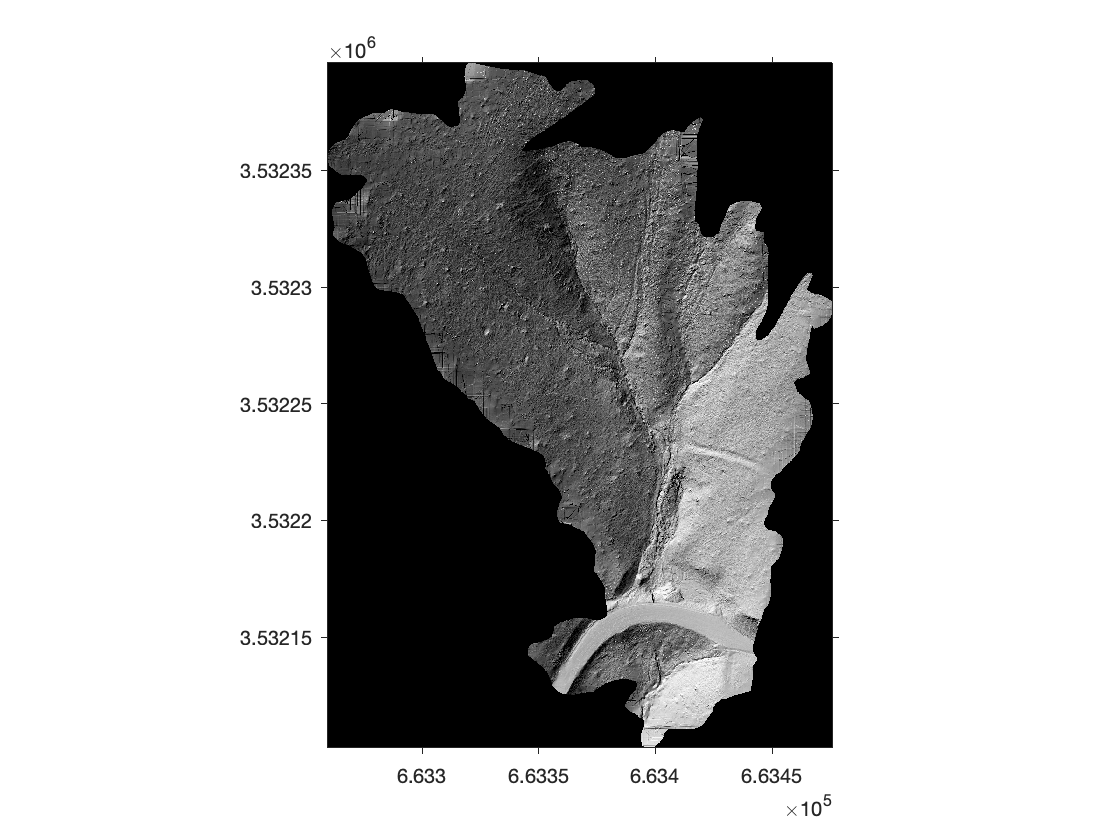

ans =   Image with properties:

           CData: [2936×2164 double]
    CDataMapping: 'scaled'

  Show all properties


% Display a shaded relief map (Fig. 2)
figure('Name','Fig. 2: Shaded relief','NumberTitle','off')
ShadePlot(dim.x,dim.y,Z)

## 2. PREPROCESS RASTERS

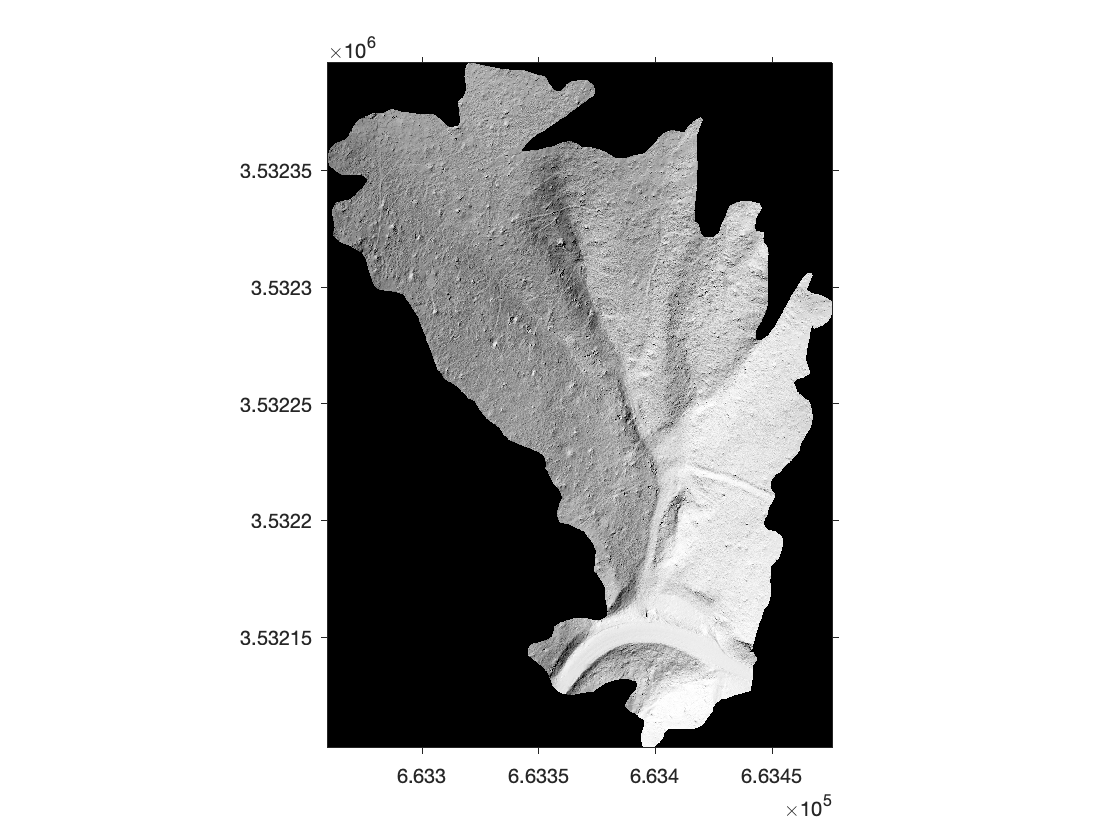

% Before calculating the power spectrum, we'll make some decisions about
% the preprocessing steps we'll take. If the DEM has a non-zero mean or a
% background slope across the entire grid, this will contaminate the
% spectrum with long-wavelength signals. So our first step will be to 
% detrend the DEM by fitting a least-squares plane to the elevations and 
% then subtracting this fit.
Zo = Z; % Save the original elevations for later
plane = Zo - Z; % Save the least-squares plane for re-trending later
Z = nanDetrend(Z);
ShadePlot(dim.x,dim.y,Z);

## 3. FILTERING

## Separate rasters into high-pass and low-pass filtered components

$1\sigma =68\ldotp 27%$, $2\sigma =95\ldotp 45%$, $3\sigma =99\ldotp 73%$ of data.

Gaussian frequency response $\hat{G} \left(f\right)$ is essentially zero by $3\sigma_f$.

Gaussian standard deviation $\sigma$ and frequency response standard deviation $\sigma_f$ are related by: $\sigma_f =\frac{1}{2\pi \sigma }$. 

Spatial wavelength $\lambda =\frac{1}{f}$ where $f$ is frequency is $\frac{\textrm{cycles}}{\left\lbrack L\right\rbrack }$. 

Therefore, the wavelength by which amplitude is nearly fully attenuated is $\lambda_0 =\frac{2\pi \sigma }{3}$.

Hence, to fully attenuate all wavelengths $<\lambda {\;}_0$, use $\sigma_f ~\frac{f_0 }{3}=\frac{1}{3\lambda_0 }\to \sigma =\frac{3\lambda_0 }{2\pi }$. 

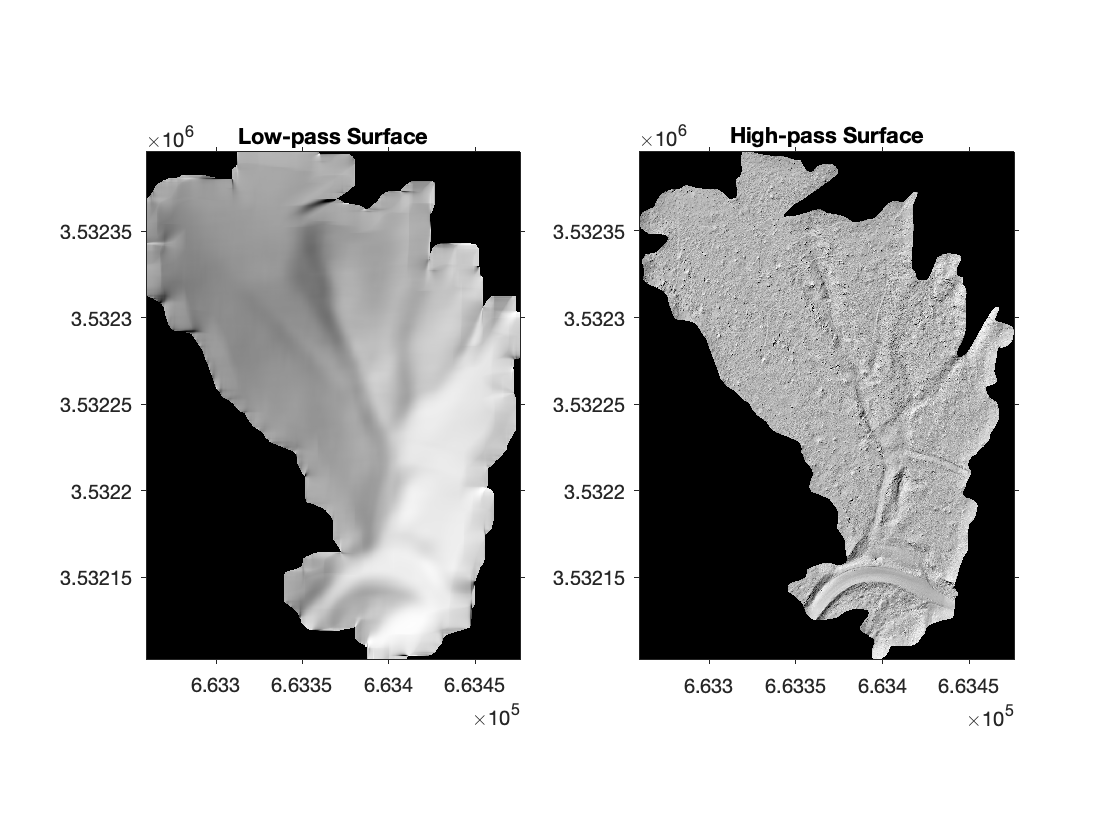

lambda0=13; %wavelength separating high and low frequencies (in m)
sigma=round(3*lambda0/(2*pi)./dx); %calculate gaussian sigma value
hsize=2.*sigma;

%Filter
[Z_lp,Z_hp]=nangaussfilt(Z,hsize,sigma);

% Display shaded relief maps of the low-pass- and high-pass-filtered data
subplot(1,2,1); 
ShadePlot(dim.x,dim.y,Z_lp); title('Low-pass Surface')
subplot(1,2,2)
ShadePlot(dim.x,dim.y,Z_hp); title('High-pass Surface')

## 2D FFT

% The fast Fourier transform proceeds fastest if the dimensions of 
% the input matrix are integer powers of two, which we can achieve by 
% padding the DEM with zeros. 
pad = 1; % 1 means pad the data, 0 no padding.

% Third, because the edges of our DEM are not perfectly periodic, the
% spectrum can become contaminated by frequencies used to "fit" the edge
% discontinuity. We can mitigate this effect by multiplying the DEM by a
% function that tapers to zero at the edges.
window = 1; % 1 means window the data, 0 no window

% Calculate the power spectrum using the 2D Fast Fourier Transform (FFT).
% Note that the zero padding and windowing happen inside fft2D.
% [Pmhp fmhp Pvhp fvhp] = fft2D(Z_hp,dx,dy,pad,window); 
% [Pmlp fmlp Pvlp fvlp] = fft2D(Z_lp,dx,dy,pad,window); 

[pxyhp,fhp] = plomb2(Z_hp, 1/dx);

Error using plomb>MarkMissingData (line 712)
Not enough data points to estimate the spectrum.

Error in plomb (line 100)
[Ch,f] = MarkMissingData(x1,t,f,nchannel,fvecSpecified,ofac,spectrumtype,freqtype,Fs);

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('plomb2', '/Users/danicaroth/Google Drive/Academic/Analysis/Scripts/Spectral_Scripts/plomb2.m', 14)" style="font-weight:bold

[pxylp,flp] = plomb2(Z_lp, 1/dx);

% A few words about the output from the previous step:
% 
% We have calculated the Discrete Fourier Transform (DFT) periodogram. This
% is different from the power spectral density, which is also commonly used
% as an estimate of the power spectrum. 
%
% Pm is the 2D power spectrum matrix, and fm is the corresponding matrix of 
% radial frequencies. Pv is a vector version of the power spectrum, and fv 
% is the corresponding vector of frequencies. Units of Pm and Pv are 
% [units of Z]^2, which in our case is length^2 since Z is a matrix of 
% elevations. Units of fm and fv are [units of x]^-1, which for us is 
% 1/length since x is distance. Figs. 3a-e show examples of a simple 1D
% signal and its power spectrum, and Fig. 3f shows an example of a simple
% surface and its 2D power spectrum.
%
% What do the units mean? The periodogram is a measure of how much of the
% original elevation field's variance falls within a given frequency range.
% You can check that the sum of the periodogram is roughly equal to the
% variance in Z. (It will be somewhat less due to the zero padding.)
%
% What about the frequency limits? Wavelength is equal to the inverse of 
% frequency. The shortest wavelength that can be resolved by 2D data is 
% oriented diagonally, and is equal to sqrt(dx^2 + dy^2), or sqrt(2) for 
% our data (Fig. 4). The longest wavelength that can be resolved is 
% infinite in principle, but in practice we wouldn't feel comfortable 
% trying to detect any signal with a wavelength longer than our dataset. To 
% be even more conservative, the longest wavelength we trust should be a 
% few times shorter than the width of the DEM -- a few hundred meters in 
% this case.

% Clean up workspace
clear pad window

% Plot the 1D version of the spectrum (Fig. 5). We'll plot the 2D spectrum 
% a few steps later, but for now it's easier to visualize in 1D.
s1d = figure('Name','Fig. 5: 1D Spectrum','NumberTitle','off');
subplot(2,1,1)
% [axfh axwh] = SpecPlot1D(fvhp,Pvhp);
[axfh axwh] = SpecPlot1D(fhp,pxyhp);
% hold on
% plot([10 10],get(axwh,'ylim'),'k')
subplot(2,1,2)
% [axfl axwl] = SpecPlot1D(fvlp,real(Pvlp));
[axfl axwl] = SpecPlot1D(flp,real(pxylp));


% Do we see anything at a 10m wavelength? Yes, there is a broad peak. The 
% shorter-wavelength peaks are just pixel-scale noise.
% hold(axwl,'on')
% plot([10 10],get(axwl,'ylim'),'k')

## Background Spectrum

% Now let's see what the spectrum looks like in 2 dimensions. If we just
% looked at it as is, we wouldn't see much: as the 1D spectrum shows,
% longer-wavelength signals have much higher power, and would swamp any
% shorter-wavelength detail. To make the 2D spectrum easier to view, we'll
% remove the power-law background trend. Because there are so many more
% points at higher frequencies, we'll bin the 1D spectrum and fit the trend
% to the binned values (Fig. 5).

nbin = 20; % Number of bins
B = bin(log10(fvhp),log10(Pvhp),nbin,0); % Bin the log-transformed data

% Plot the binned values
hold(axfl,'on')

plot(axfl,10.^B(:,1),10.^B(:,2),'ok','markerfacecolor','w')
hold(axfh,'on')
plot(axfh,10.^B(:,1),10.^B(:,2),'ok','markerfacecolor','w')

% Fit a trend with the form P ~ 1/f^n, and plot it
fit = robustfit(B(:,1),B(:,2));
plot(axfh,10.^B(:,1),10^fit(1)*(10.^B(:,1)).^fit(2),'k')

## 2D Power Spectrum

% Use this fit to normalize the 2D spectrum
Pmn = Pmhp./(10^fit(1)*fmhp.^fit(2));

% Plot the normalized 2D spectrum (Fig. 6)
figure('Name','Fig. 6: 2D Spectrum','NumberTitle','off')
SpecPlot2D(fmhp,log10(Pmn));

% We see a radially symmetric pattern because the roughness doesn't appear
% to have a strongly preferred orientation over the entire landscape. 
% The two peaks very close to the center of the square correspond to the 
% NW-SE-trending valleys, and the sharp features aligned with these peaks 
% at higher frequencies are probably harmonics.

% Clean up workspace
clear Pm fm Pv nbin B axf axw fit Pmn

## Remove edge effects

% You can also see some edge effects produced by the removal of long 
% wavelengths. Let's clip these off. Based on the low-pass figure, it
% looks like the edge effects extend for about ~6 m from the edges of the
% raster, so we'll be safe and clip 8 m.
clear clipx clipy
edgeelements=8./dx; %8 m
edge=edgebuffer(Z,edgeelements);
Z_hp=Z_hp+edge;
Z_lp=Z_lp+edge;

% Display shaded relief maps of the low-pass- and high-pass-filtered data
subplot(1,2,1); 
 title('Low-pass Cleaned Surface')
subplot(1,2,2)
ShadePlot(dim.x,dim.y,Z_hp); title('High-pass Cleaned Surface')

## 5. WINDOWED SPECTRAL ANALYSIS 

## Windowed 2D FFT

% Now that we have isolated the mounds from the background topography, we
% can investigate how they vary across the landscape. The spectral analysis
% we performed previously only provides a measure of average mound
% characteristics across the entire DEM, but the lidar data is sufficiently
% dense that we can compute multiple spectra within smaller windows across
% the DEM, and derive a measure of mound characteristics within each window.
Z_hp(isnan(Z_hp))=0;

xwin = 1./dx; ywin = 1./dy; % Window dimensions in meters
xstep = 1; ystep = 1; % Distances between successive window positions
[ic jc wavelength angle variance] = ...
    fftWin(Z_hp,dy,dx,xwin,ywin,xstep,ystep);

% Visualize the results of the windowed analysis by overlaying them on
% a shaded relief map of the original DEM:
opacity = 0.25;

## Wavelength

% Weighted mean wavelength within a moving window (which shows
% spatial variability in the mound wavelength), overlaid on shaded relief
% of unfiltered DEM. Color scale is capped at a wavelength of 15m.
figure('Name','Wavelength map','NumberTitle','off');
wmax = 15;
wavelength(wavelength>wmax) = wmax; % Avoid scale saturation in channels
CShadePlot(dim.x,dim.y,Z,dim.x(jc),dim.y(ic),wavelength,opacity); 
title('Dominant wavelength (m)')

## Variance

% Fig. 9. Variance of elevation within a moving window (which provides a
% local measure of roughness amplitude) overlaid on shaded relief of unfiltered
% DEM
figure('Name','Variance map','NumberTitle','off');
CShadePlot(dim.x,dim.y,Z,dim.x(jc),dim.y(ic),variance,opacity); 
title('Variance (m^2)')

## Orientation

% Direction of roughness elongation within a moving window, overlaid
% on shaded relief of unfiltered DEM 
angle = angle+90; % Convert wave direction to mound elongation direction
angle(angle<0) = angle(angle<0)+360;
angle = angle - 180; % Make all values 0 to 180
figure('Name','Fig. 11: Orientation map','NumberTitle','off');
CShadePlot(dim.x,dim.y,Z,dim.x(jc),dim.y(ic),angle,opacity); 
title('Roughness orientation (degrees CCW from E)')

% Clean up workspace
clear xwin ywin xstep ystep wmax

## 6. ANALYSIS OF MOUND CHARACTERISTICS 

## Does mound variance depend on slope?

% Fig. 12. Mound variance vs. topographic slope
G = G(ic,jc);
figure('Name','Fig. 12: Mound variance vs. Slope','NumberTitle','off');
chan = chan(ic,jc); % A channel map at the windowed resolution

## Add point density map

% There are so many lidar points that it's useful to include a point
% density map to make trends clearer:
scattercloud(G(~chan),variance(~chan),25,1,'.k','jet');
xlabel('Gradient')
ylabel('Variance (m^2)');
set(gca,'tickdir','out')
% We can see that mound variance is typically highest on gentle slopes, and
% declines as slopes steepen (Fig. 12).

## Does mound variance depend on aspect?

D = D(ic,jc);
figure('Name','Fig. 13: Mound variance vs. Aspect','NumberTitle','off');
h1 = polar(D(~chan),variance(~chan),'.');
set(h1,'MarkerEdgeColor',[.5 .5 .5])
d = bin(D(:),variance(:),24,0);
hold on
h2 = polar(d(:,1),d(:,8),'-ok');
set(h2,'MarkerFaceColor','y','MarkerSize',10)
title('Mound variance (m^2) vs. slope aspect (degrees CCW from E)')
% Mounds are taller on NE-facing slopes, and shorter on SW-facing slopes
% (Fig. 13).

## We can make the trend more apparent by looking only at the binned values:

set(h1,'visible','off')

## Are mounds aligned or elongated in the downslope direction?

% Fig. 14. Mound orientation vs. slope orientation
O = D;  
O(O<0)=O(O<0)+pi; % Make all slope orientations 0 - 180 deg
Gmin = 0.1; % Minimum gradient -- we don't expect a strong relationship on
            % gentle slopes
figure('Name','Fig. 14: Mound orientation vs. Aspect','NumberTitle','off');
scattercloud(rad2deg(O(~chan & G>Gmin)),angle(~chan & G>Gmin),25,1,'.k','jet');
axis square
hold on
plot([0 180],[0 180],'w')
xlabel('Slope orientation (deg CCW from E)');
ylabel('Mound orientation (deg CCW from E)');
title('Gradient > 0.1')
set(gca,'tickdir','out','xlim',[0 180],'ylim',[0 180])
% It's noisy, but the clustering around the 1:1 line suggests that the
% mounds are preferentially elongated in the downslope direction (Fig. 14).

## How much energy is required to form a mound?

If mounds are formed by transporting soil from troughs to peaks, then a rough estimate of the work W required to build a mound is W = rho*g*V*h where rho is soil density, g is gravity, V is the volume of soil moved from trough to peak, and h is the vertical distance the soil's center of mass was displaced, which is roughly equal to half the mound height:   /\ /\  h / \/ \

If the mound wavelength is lambda, then V ~ h*lambda^2. So our estimate of the work required to build a mound is:

rho = 2200; % density in (kg m^-3)
g = 10; % gravitational acceleration (m s^-2)
h = sqrt(variance); % Standard deviation (m), an estimate of h
W = rho*g*h.^2.*wavelength.^2; % Work in (J)

% Plot energy expenditure over shaded relief (Fig. 15)
figure('Name','Fig. 15: Energy expenditure','NumberTitle','off');
CShadePlot(dim.x,dim.y,Z,xhp(jc),yhp(ic),W/1000,opacity); 
title('Energy expenditure (kJ)')

% Clean up workspace
clear G C D O chan s d h1 h2 Gmin rho g opacity

## %%%%%%%%%%%%%%

7. DE-NOISING %

%%%%%%%%%%%%%%%%%

## A noisy DEM

% What if we want to eliminate, rather than isolate, a component of a
% surface? Noise removal is a common filtering operation, and there is an
% optimal way to construct the filter. 

% Add some Gaussian noise to the elevations in the spatial domain to create 
% a noisy DEM (Fig. 16)
sigma = 0.2; % Standard deviation of the noise in meters
No = Zo + sigma*randn(Ny,Nx); % Noisy elevations
figure('Name','Fig. 16: Noisy DEM','NumberTitle','off'); 
ShadePlot(dim.x,dim.y,No);

## Power spectrum

% Get the 2D Power spectrum using the same steps outlined above
N = Detrend(No);
plane = No - N; % Save the least-squares plane for re-trending later
pad = 1;
window = 1;
[Pmhp, fmhp Pvhp fvhp] = fft2D(N,dx,dy,pad,window); 

% Plot the 1D version of the spectrum (Fig. 17)
figure('Name','Fig. 17: 1D Spectrum of noisy DEM','NumberTitle','off');
axf = SpecPlot1D(fvhp,Pvhp);

nbin = 20;
B = bin(log10(fvhp),log10(Pvhp),nbin,0);

hold(axf,'on')
plot(axf,10.^B(:,1),10.^B(:,2),'ok','markerfacecolor','w')

## Noise estimation

% Next, we manually identify parts of the spectrum that appear to be
% dominated by noise. The high-frequency end of the spectrum is flat, the
% expected trend for white noise (Fig. 17).
imeas = 1:20; % Bins that correspond to the measured spectrum (all of them)
inoise = 17:20; % Bins that are dominated by noise

% Extrapolate the inferred noise spectrum to parts of the spectrum that are
% dominated by signal. In this case, we can capture the assumed shape of 
% the noise spectrum pretty well with a constant value.
noise = 10.^min(B(inoise,2)) * ones(size(fmhp));

% Fit a smooth surface to the measured spectrum by interpolating linearly
% between the binned values.
measured = interp1(B(imeas,1),B(imeas,2),log10(fmhp));
measured = 10.^measured; % Transform back to linear spectral power
measured(isnan(measured)) = 0; % Elements that couldn't be interpolated


% Plot the measured and inferred spectra (Fig. 17)
plot(axf,fmhp(:),measured(:),'+k')
plot(axf,fmhp(:),noise(:),'+b')

## Filter construction

% Estimate the true signal spectrum by subtracting the estimated noise
% spectrum from the measured spectrum. The optimal filter is then 
% constructed by taking the ratio of the estimated signal spectrum to the
% measured spectrum. The filter will be nearly 1 at frequencies where the 
% spectrum is dominated by signal, and nearly zero where it is dominated by
% noise -- just what we want.
signal = measured - noise; 
F = signal./measured;
F(F==Inf | F==-Inf) = 0; % Correct elements where we just divided by zero

## Noise removal

% Now we do the filtering. This time we don't window the DEM, because we
% want to preserve the actual elevations. 
padsize = 1024; % Next highest power of 2
N = fftshift(fft2(N,padsize,padsize)); % Fourier transform of noisy DEM
N = ifft2(ifftshift(N.*F)); % Inverse transform of filtered FT
N = plane + N(1:Ny,1:Nx); % Clip off the padding from the de-noised DEM and
                          % re-trend by adding the least-squares plane

## View de-noised DEM

% Plot the de-noised DEM (Fig. 18)
figure('Name','Fig. 18: De-noised DEM','NumberTitle','off');
ShadePlot(dim.x,dim.y,N);

% Clean up workspace
clear sigma plane pad window Pm fm Pv fv axf nbin B imeas inoise noise measured signal F padsize

## %%%%%%%%%%%%%%%

8. SAVE OUTPUT %

%%%%%%%%%%%%%%%%%%

## Save workspace

save mima

## Export grids

% Should we want to use any of the filtered grids in a GIS, we can use the
% included function that writes an Arc-formatted ASCII grid. This grid
% can then be imported directly into ArcMap, or converted to ESRI's binary
% grid format using the ASCIIGRID command in ArcInfo or the "ASCII to
% Raster" function in ArcToolbox. Examples:

% The high-pass-filtered topography
WriteArcGrid(xhp,yhp,Zhp,'merced_highpass')

% The map of mound wavelength
WriteArcGrid(xhp(jc),yhp(ic),wavelength,'wavelength')